clear;
load("Iout.mat");
load("Vout.mat");

[first, last, mmax, bmax, Nmax] = linefit(Vout(65:96), Iout(65:96), 5e-4)

first = 6

last = 16

mmax = 6.4855e-06

bmax = -2.6633e-05

Nmax = 11


1/mmax

ans = 1.5419e+05

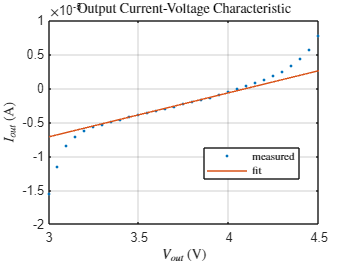


plot(Vout, Iout,'.');
hold on;
plot(Vout, Vout*mmax + bmax);
grid on;
xlim([3, 4.5])
title("Output Current-Voltage Characteristic","Interpreter","latex")
xlabel("$V_{out}$ (V)","Interpreter","latex")
ylabel("$I_{out}$ (A)","Interpreter","latex")
legend("measured","fit","Interpreter","latex","Location","best")
hold off;